# Final Project

## System Overview

<insert diagram here>

The two-step noise reduction system builds on top of the Wiener filter process of noise reduction and the decision-directed approach. Using the noise profile taken from the first 3 seconds of the noisy signal and the frequency representation of the noisy signal, a transfer function is computed using the two-step SNR method. The multiplicative gain calculated from the decision-directed approach further refines a priori SNR estimation and the subsequent now 2-step multiplicative gain, giving a more accurate power spectrum density estimate of the noisy signal. After the 2-step multiplicative gain is applied to the frequency-domain representation of the noisy signal, it is finally converted back to the time-domain.

**No MATLAB toolbox dependencies.**

## **References**

[1]    A. Zaknich, *Principles of adaptive filters and self-learning systems*. London: Springer London, 2005.

[2]    C. Plapous, C. Marro, Laurent Mauuary, and Pascal Scalart, “A two-step noise reduction technique,” *International Conference on Acoustics, Speech, and Signal Processing*, May 2004, doi: [https://doi.org/10.1109/icassp.2004.1325979](https://doi.org/10.1109/icassp.2004.1325979).

[3]    Pankai Gael, P. Saxena, M. Chandra, and V. K. Gupta, “Comparative analysis of speech enhancement methods,” *Wireless and Optical Communications Networks*, Jul. 2013, doi: [https://doi.org/10.1109/wocn.2013.6616238](https://doi.org/10.1109/wocn.2013.6616238).

[4]    A. Ouardia and F. Merazka , "Denoising of Speech Signal Using Decision Directed Approach", *International Journal of Informatics and Applied Mathematics*, vol. 3, no. 1, pp. 70-83, Jun. 2020

[5]    C. Plapous, C. Marro, and P. Scalart, “Improved Signal-to-Noise Ratio Estimation for Speech Enhancement,” *IEEE Transactions on Audio, Speech and Language Processing*, vol. 14, no. 6, pp. 2098–2108, Nov. 2006, doi: [https://doi.org/10.1109/tasl.2006.872621](https://doi.org/10.1109/tasl.2006.872621).

[6]    P. Scalart and J. V. Filho, “Speech enhancement based on a priori signal to noise estimation,” *1996 IEEE International Conference on Acoustics, Speech, and Signal Processing Conference Proceedings*, doi: [https://doi.org/10.1109/icassp.1996.543199](https://doi.org/10.1109/icassp.1996.543199).

[7]    C. Plapous, C. Marro, and Pascal Scalart, “Speech Enhancement Using Harmonic Regeneration,” *International Conference on Acoustics, Speech, and Signal Processing*, Mar. 2005, doi: [https://doi.org/10.1109/icassp.2005.1415074](https://doi.org/10.1109/icassp.2005.1415074).

[8]    G. Welch and G. Bishop, “An Introduction to the Kalman Filter.” Available: [https://perso.crans.org/club-krobot/doc/kalman.pdf](https://perso.crans.org/club-krobot/doc/kalman.pdf)

[9]    A. Sarafnia and Seyed Ghorshi, “Noise reduction of speech signal using bayesian state-space Kalman filter,” *Asia-Pacific Conference on Communications*, Aug. 2013, doi: [https://doi.org/10.1109/apcc.2013.6766008](https://doi.org/10.1109/apcc.2013.6766008).

[10]    F. G. Encinas, L. A. Silva, A. S. Mendes, G. V. Gonzalez, V. R. Q. Leithardt, and J. F. De Paz Santana, “Singular Spectrum Analysis for Source Separation in Drone-Based Audio Recording,” *IEEE Access*, vol. 9, pp. 43444–43457, 2021, doi: [https://doi.org/10.1109/access.2021.3065775.](https://doi.org/10.1109/access.2021.3065775.)

## Contributions

- Noel Alben: research and implementation

- Joann Ching: evaluation function & bug testing

- Pavan Seshadri: profiler, data loader

- Karthik Varadharajan: description, flowchart, main.mlx 

## Infor infor

xxx-xxx-xxx

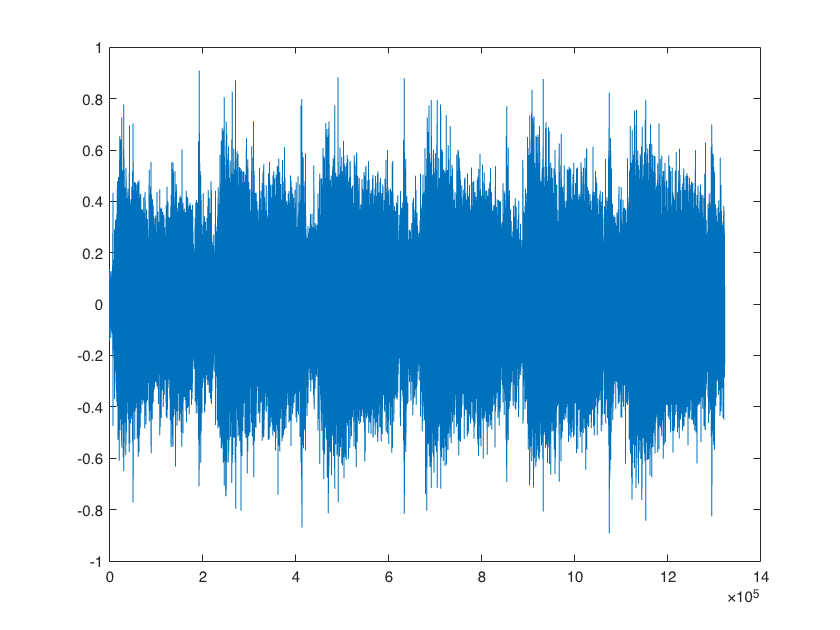

[x,fs] = audioread('../noisy.wav');
plot(x);

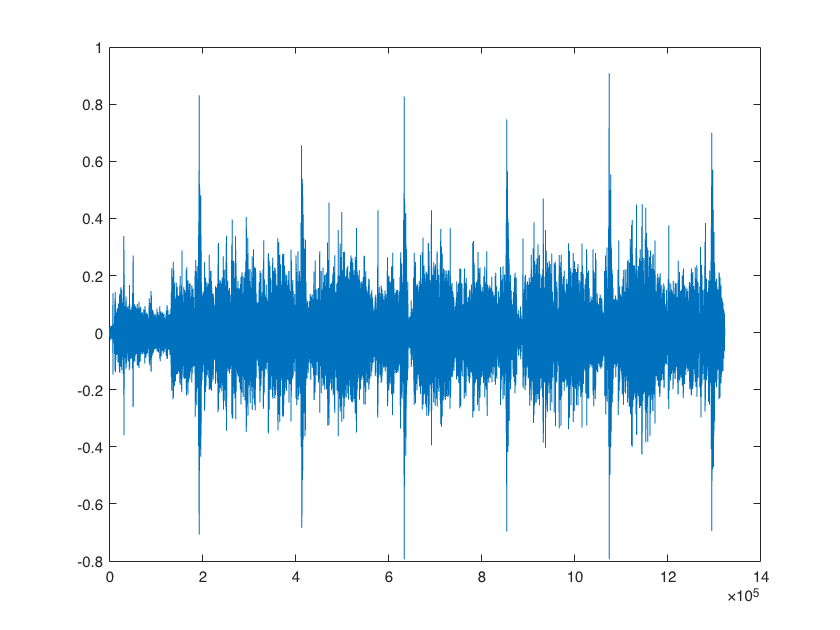

xhat = denoise(x, fs);
plot(xhat);

[cleanSig, fs] = audioread('../clean.wav');
result_snr = computeSnr(cleanSig, xhat)

ans = 2.0776

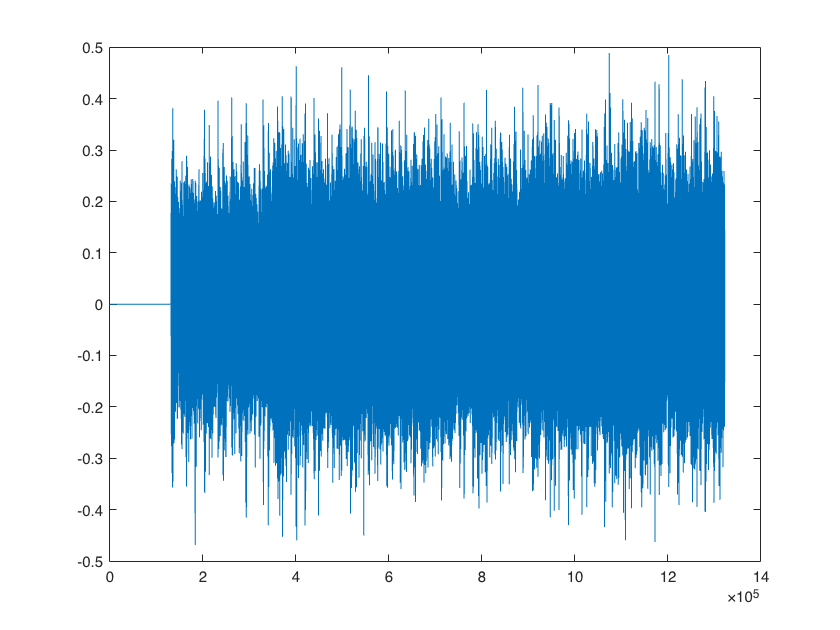

plot(cleanSig);

### Evaluate

exp_name = 'test';
data = result_snr;

Unrecognized function or variable 'result_snr'.

filename = './results.txt';
evaluate(filename, exp_name, result_snr, x, xhat)

devDataPath = "/Users/noelalben/Desktop/DSP_finalProject/music-denoising-spring2023/data/dev";

devDataFolders = ls(devDataPath);
% For unix and macbook
devDataFolders = strsplit(devDataFolders)

devDataFolders = 1×201 cell array
    {'000'}    {'013'}    {'026'}    {'039'}    {'052'}    {'065'}    {'078'}    {'091'}    {'104'}    {'117'}    {'130'}    {'143'}    {'156'}    {'169'}    {'182'}    {'195'}    {'001'}    {'014'}    {'027'}    {'040'}    {'053'}    {'066'}    {'079'}    {'092'}    {'105'}    {'118'}    {'131'}    {'144'}    {'157'}    {'170'}    {'183'}    {'196'}    {'002'}    {'015'}    {'028'}    {'041'}    {'054'}    {'067'}    {'080'}    {'093'}    {'106'}    {'119'}    {'132'}    {'145'}    {'158'}    {'171'}    {'184'}    {'197'}    {'003'}    {'016'}    {'029'}    {'042'}    {'055'}    {'068'}    {'081'}    {'094'}    {'107'}    {'120'}    {'133'}    {'146'}    {'159'}    {'172'}    {'185'}    {'198'}    {'004'}    {'017'}    {'030'}    {'043'}    {'056'}    {'069'}    {'082'}    {'095'}    {'108'}    {'121'}    {'134'}    {'147'}    {'160'}    {'173'}    {'186'}    {'199'}    {'005'}    {'018'}    {'031'}    {'044'}    {'057'}    {'070'}    {'083'}    {'096


nDevSamples = size(devDataFolders, 2)-1;

initSnr = NaN(nDevSamples, 1);
finalSnr = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i), "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i), "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);

    estimSig = denoise(noisySig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);
    disp(initSnr(i))
    finalSnr(i) = computeSnr(cleanSig, estimSig);    
end

deltaSnr = finalSnr - initSnr;

fprintf("Input SNR (dB)");
descStats(initSnr);

fprintf("Output SNR (dB)");
descStats(finalSnr);

fprintf("Change in SNR (dB)");
descStats(deltaSnr);